# FCN Surrogate Modeling for DO supply model

- `本脚本用于河岸带溶解氧供应模型的替代建模`

- `数据来自2022.12生成的1000+300组样本`

- `替代模型方法为卷积神经网络（CNN)`

## `1. 准备数据`

clear;
rng(1)

num = 1200;
t = 7; % d
[TrainX, TrainY, N1, PS] = loadset('E:\深度学习Model\DO supply New\ProductData\VG20%2\Trainset22.mat', [], 1, t, num);
[TestX, TestY, N] = loadset('E:\深度学习Model\DO supply New\ProductData\VG20%2\Test\Testset22.mat', PS, 0, t, 300);
% id = randperm(size(TrainX,4),0.5*size(TrainX,4));
% TrainX = TrainX(:, :, :, id); TrainY = TrainY(:, :, :, id);

% id = randperm(N,N);
% TestX = TestX(:, :, :, id);TestY = TestY(:, :, :, id);
validX = TestX(:, :, :, 1:fix(0.4*N));validY = TestY(:, :, :, 1:fix(0.4*N));
TestX = TestX(:, :, :, fix(0.4*N)+1:end);TestY = TestY(:, :, :, fix(0.4*N)+1:end);

## 2. 模型

layers = [
    imageInputLayer([1 1 11],"Name","imageinput")
    fullyConnectedLayer(100,"Name","fc")
    projectAndReshapeLayer([4 8 512],100,"Name","proj")
    transposedConv2dLayer([3 3],512,"Name","transposed-conv_4","Cropping","same")
    batchNormalizationLayer("Name","batchnorm_4")
    leakyReluLayer(0.001,"Name","leakyrelu_4")
    transposedConv2dLayer([3 3],256,"Name","transposed-conv_8","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_8")
    leakyReluLayer(0.001,"Name","leakyrelu_8")
    transposedConv2dLayer([3 3],128,"Name","transposed-conv_16","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_16")
    leakyReluLayer(0.001,"Name","leakyrelu_16")
    transposedConv2dLayer([3 3],64,"Name","transposed-conv_32","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_32")
    leakyReluLayer(0.001,"Name","leakyrelu_32")
    transposedConv2dLayer([3 3],32,"Name","transposed-conv_64_1","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_64")
    leakyReluLayer(0.001,"Name","leakyrelu_64")
    transposedConv2dLayer([3 3],1,"Name","transposed-conv_64_2","Cropping","same")
    regressionLayer("Name","regressionoutput")];

lgraph = layerGraph();

tempLayers = [
    imageInputLayer([1 1 11],"Name","imageinput")
    fullyConnectedLayer(100,"Name","fc")
    projectAndReshapeLayer([4 8 512],100,"Name","proj")
%     dropoutLayer(0.5,"Name","dropout")
    transposedConv2dLayer([2 2],512,"Name","transposed-conv_4","Cropping","same")
    batchNormalizationLayer("Name","batchnorm_4")
    leakyReluLayer(0.01,"Name","leakyrelu_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    transposedConv2dLayer([3 3],256,"Name","transposed-conv_8","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_8")
    leakyReluLayer(0.01,"Name","leakyrelu_8")
    transposedConv2dLayer([3 3],256,"Name","transposed-conv_8_1","Cropping","same")
    batchNormalizationLayer("Name","batchnorm_8_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    transposedConv2dLayer([1 1],256,"Name","transposed-conv_8_2","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_8_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_8")
    leakyReluLayer(0.01,"Name","leakyrelu_8_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    transposedConv2dLayer([3 3],128,"Name","transposed-conv_16","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_16")
    leakyReluLayer(0.01,"Name","leakyrelu_16")
    transposedConv2dLayer([3 3],128,"Name","transposed-conv_16_1","Cropping","same")
    batchNormalizationLayer("Name","batchnorm_16_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    transposedConv2dLayer([1 1],128,"Name","transposed-conv_16_2","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_16_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_16")
    leakyReluLayer(0.01,"Name","leakyrelu_16_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    transposedConv2dLayer([1 1],64,"Name","transposed-conv_32_2","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_32_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    transposedConv2dLayer([5 5],64,"Name","transposed-conv_32","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_32")
    leakyReluLayer(0.01,"Name","leakyrelu_32")
    transposedConv2dLayer([5 5],64,"Name","transposed-conv_32_1","Cropping","same")
    batchNormalizationLayer("Name","batchnorm_32_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_32")
    leakyReluLayer(0.01,"Name","leakyrelu_32_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    transposedConv2dLayer([1 1],32,"Name","transposed-conv_64_2","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_64_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    transposedConv2dLayer([5 5],32,"Name","transposed-conv_64","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_64")
    leakyReluLayer(0.01,"Name","leakyrelu_64")
    transposedConv2dLayer([5 5],32,"Name","transposed-conv_64_1","Cropping","same")
    batchNormalizationLayer("Name","batchnorm_64_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_64")
    leakyReluLayer(0.01,"Name","leakyrelu_64_1")
    transposedConv2dLayer([5 5],1,"Name","transposed-conv_out","Cropping","same")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% 清理辅助变量
clear tempLayers;

lgraph = connectLayers(lgraph,"leakyrelu_4","transposed-conv_8");
lgraph = connectLayers(lgraph,"leakyrelu_4","transposed-conv_8_2");
lgraph = connectLayers(lgraph,"batchnorm_8_2","addition_8/in1");
lgraph = connectLayers(lgraph,"batchnorm_8_1","addition_8/in2");
lgraph = connectLayers(lgraph,"leakyrelu_8_1","transposed-conv_16");
lgraph = connectLayers(lgraph,"leakyrelu_8_1","transposed-conv_16_2");
lgraph = connectLayers(lgraph,"batchnorm_16_2","addition_16/in1");
lgraph = connectLayers(lgraph,"batchnorm_16_1","addition_16/in2");
lgraph = connectLayers(lgraph,"leakyrelu_16_1","transposed-conv_32_2");
lgraph = connectLayers(lgraph,"leakyrelu_16_1","transposed-conv_32");
lgraph = connectLayers(lgraph,"batchnorm_32_2","addition_32/in1");
lgraph = connectLayers(lgraph,"batchnorm_32_1","addition_32/in2");
lgraph = connectLayers(lgraph,"leakyrelu_32_1","transposed-conv_64_2");
lgraph = connectLayers(lgraph,"leakyrelu_32_1","transposed-conv_64");
lgraph = connectLayers(lgraph,"batchnorm_64_1","addition_64/in2");
lgraph = connectLayers(lgraph,"batchnorm_64_2","addition_64/in1");

% [4 8 512]; no dropoutLayer; leakyReluLayer 0.01; [5 5],64;

## 3.训练参数

在单 GPU 上训练。
正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０４　｜　　　　　１１３．６４　｜　　　　２７０．９８　｜　６４５６．９８７８　｜　３６７１４．７５３９　｜　　０．００５０　｜
｜　　　６　｜　　　５０　｜　　　　　００：００：２４　｜　　　　　　　６．５０　｜　　　　　　６．３９　｜　２１．１２１５　｜　２０．４４５９　｜　　０．００５０　｜
｜　　１２　｜　　１００　｜　　　　　００：００：４１　｜　　　　　　　５．１１　｜　　　　　　５．２６　｜　１３．０７７７　｜　１３．８１９３　｜　　０．００５０　｜
｜　　１７　｜　　１５０　｜　　　　　００：００：５９　｜　　　　　　　３．８６　｜　　　　　　３．７５　｜　　７．４６４８　｜　７．０２７０　｜　　０．００５０　｜
｜　　２３　｜　　２００　｜　　　　　００：０１：１５　｜　　　　　　　２．５８　｜　　　　　　２．８１　｜　　３．３２１０　｜　３．９３６５　｜　　０．００５０　｜
｜　　２８　｜　　２５０　｜　　　　　００：０１：３１　｜　　　　　　　２．６３　｜　　　　　　２．４２　｜　　３．４５４７　｜　２．９１７６　｜　　０．００５０　｜
｜　　３４　｜　　３００　｜　　　　　００：０１：４６　｜　　　　　　　２．５８　｜　　　　　　２．９９　｜　　３．３１７８　｜　４．４６７９　｜　　０．００５０　｜
｜　　３９　｜　　３５０　｜　　　　　００：０２：０２　｜　　　　　　　２．４５　｜

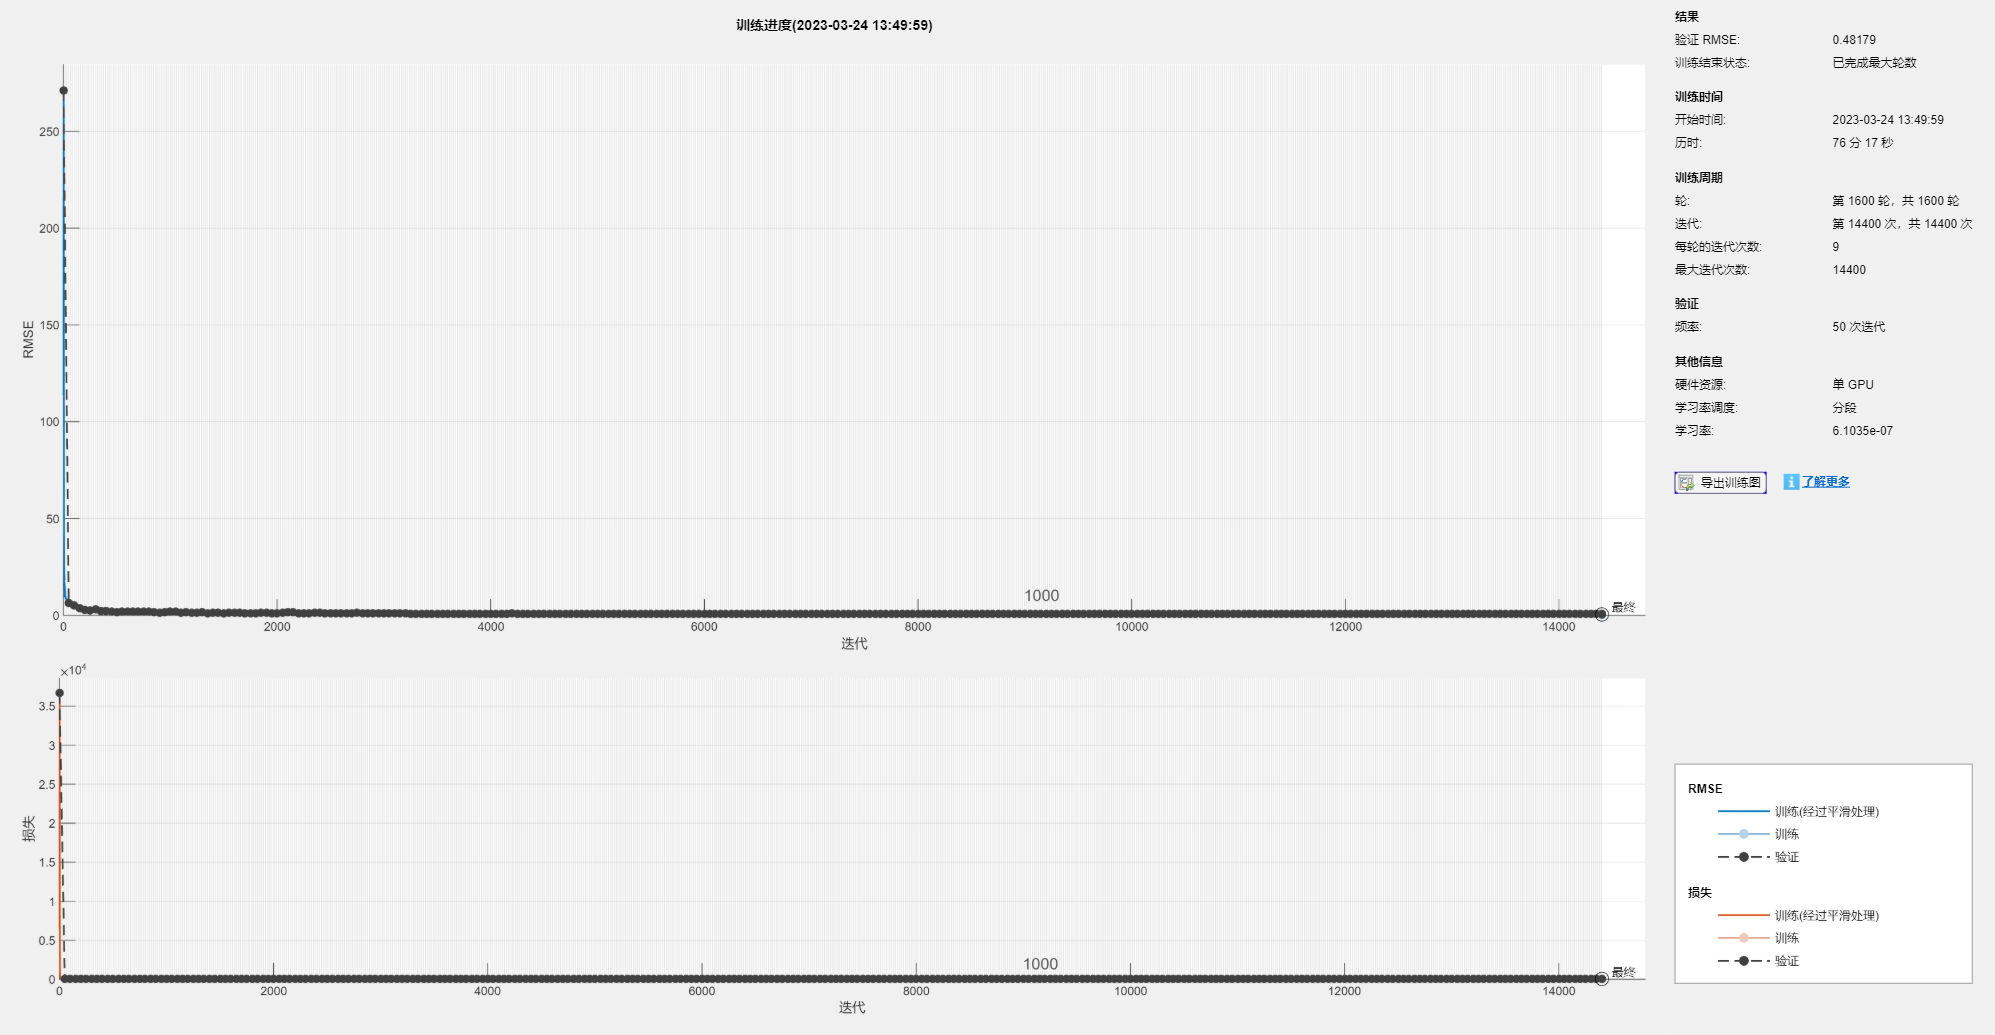

options = trainingOptions('adam', ...%rmsprop adam sgdm
    'Shuffle','every-epoch' ,...
    'MaxEpochs',1600, ...
    'MiniBatchSize',128, ...
    'shuffle', 'every-epoch', ... % 'every-epoch' 'never'
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.5, ...
    'LearnRateDropPeriod',120, ...
    'InitialLearnRate',0.005, ...
    'GradientThreshold',1, ...
    'ValidationData',{validX,validY},...
    'Verbose',true,...
    'Plots','training-progress');

rng(99)
net_cnn = trainNetwork(TrainX,TrainY,lgraph,options); % [0 rng(1,99) 0.61 0.5692]

YPred = predict(net_cnn,TestX);
YPred=double(YPred);
MSE = 2*mse(dlarray(YPred,'SSCB'),dlarray(TestY,'SSCB'))

MSE =   1×1 dlarray

    0.2846


RV = abs(var(TestY,0,4)-var(YPred,0,4))./var(TestY,0,4);
[mae, rmse, r2, rae,msssim] = performance(YPred, TestY, 0);
[a1, a2, a3, a4, a5] = performance(YPred, TestY, 1)

a1 = 9.9493e-04

a2 = 0.0059

a3 = 0.9756

a4 = 0.0196

a5 = 0.9998

mean(mae,'all')

ans = 9.9493e-04

mean(rmse,'all')

ans = 0.0028

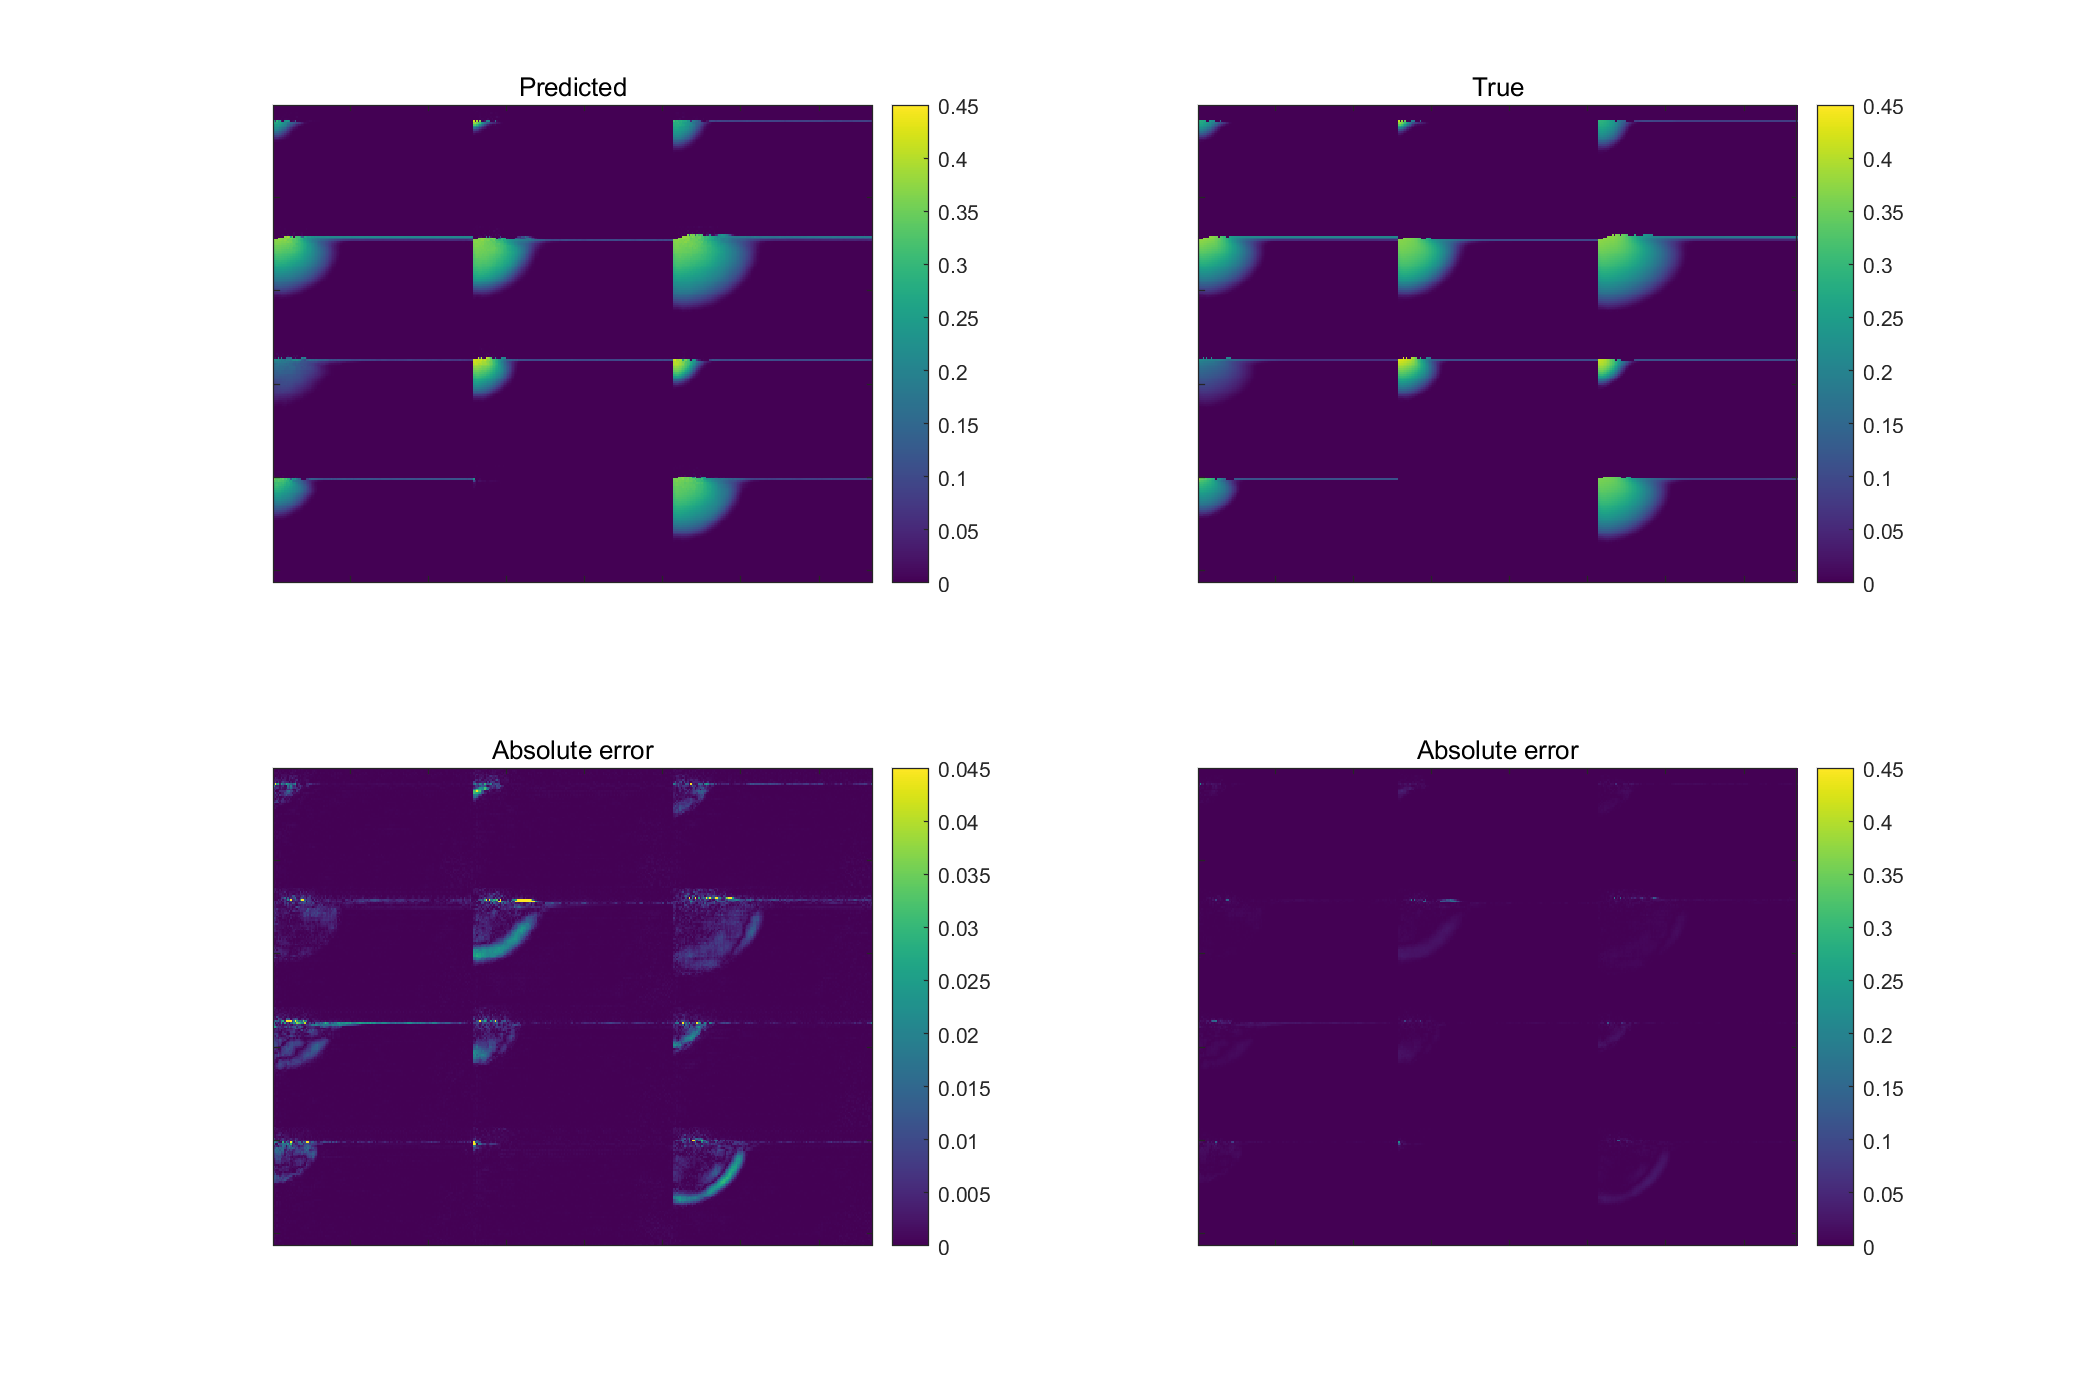

fig_more(YPred, TestY, 150, 0.45)

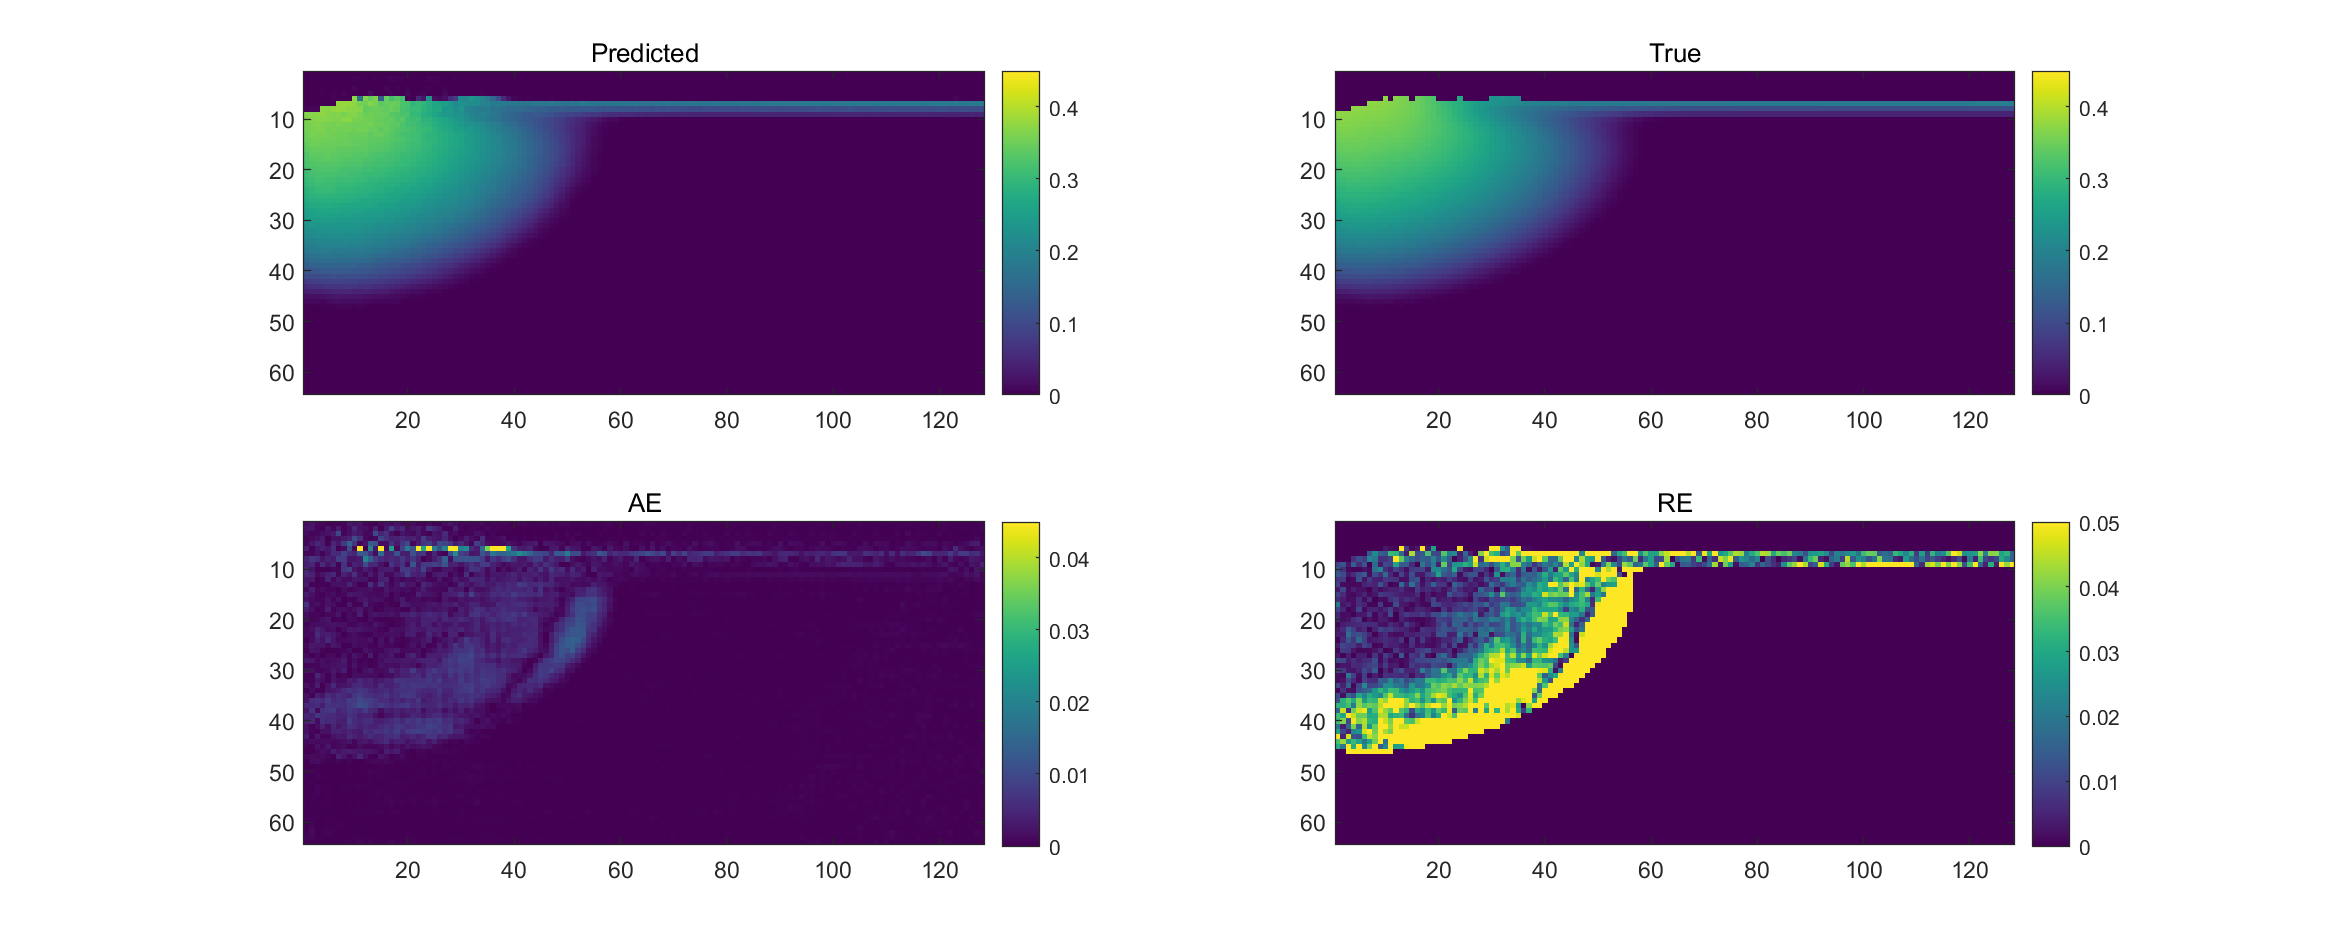

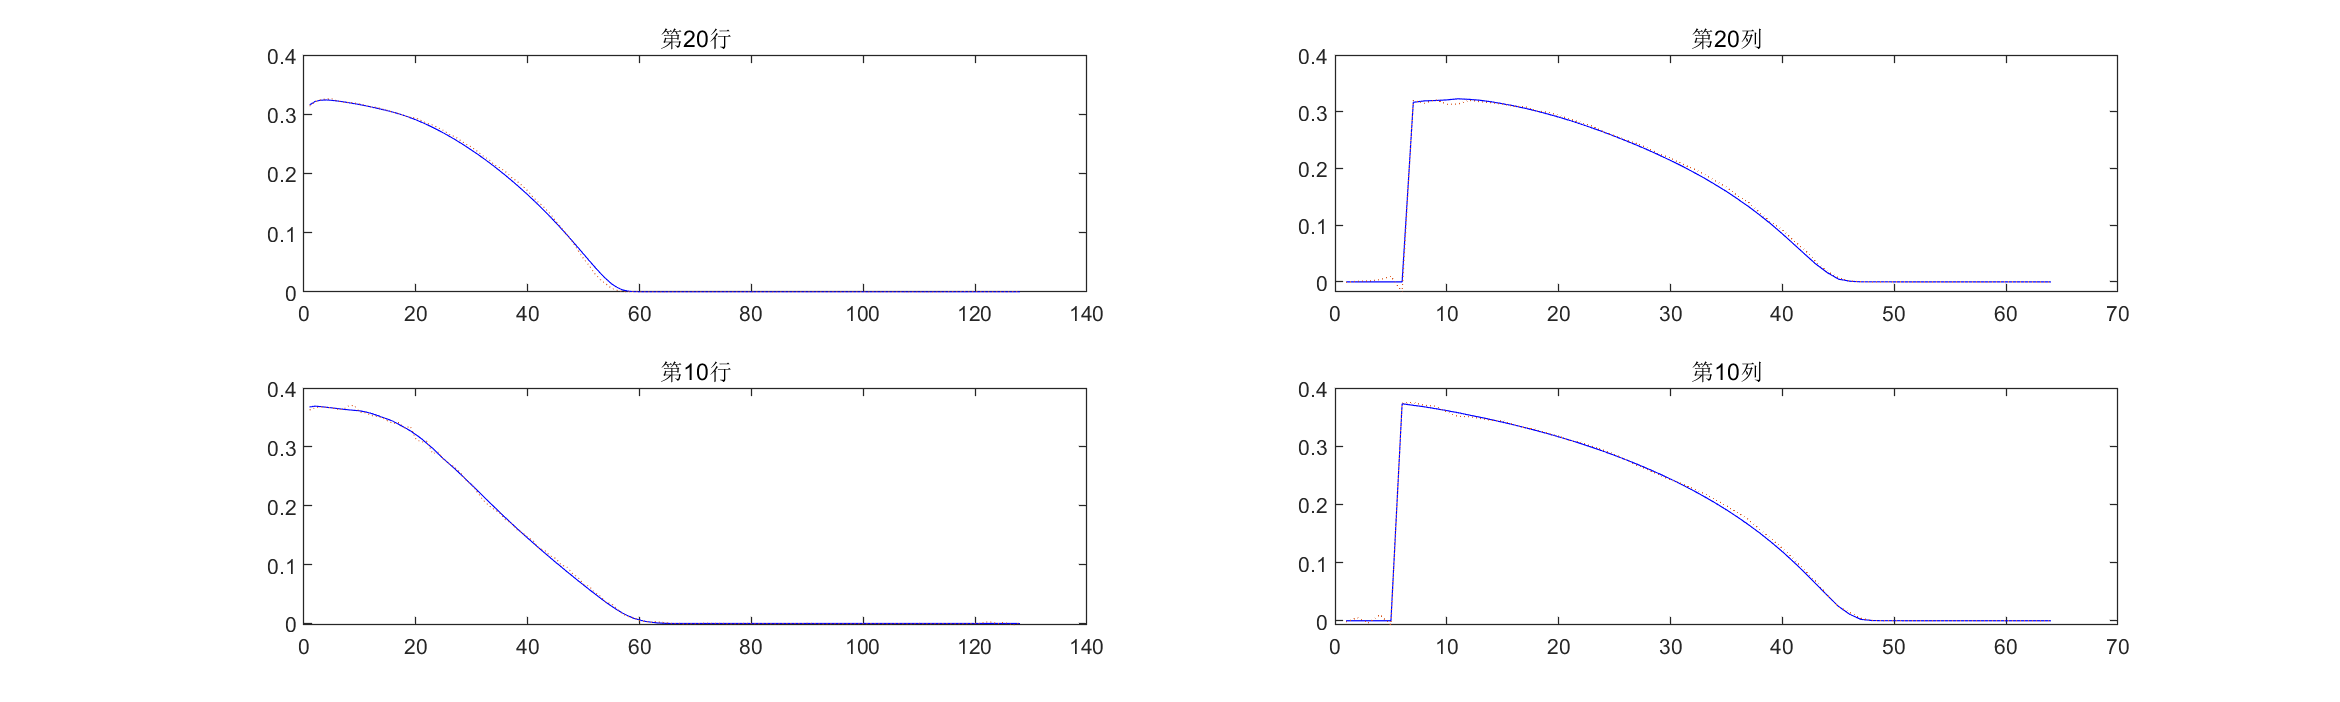

fig_one(YPred, TestY, 155, 0.45)

- 加载数据

function [X, Y, N, PS] = loadset(filename, PS, map, tid, num)
    DS = load(filename);
    [len, t] = size(DS.dataset);
    [H, W] = size(DS.dataset(1,t).DOfield);

    if num ~= 0
        len = num;
    end

    X = zeros(1, 1 , 11, len);
    Y = zeros(H, W, 1, len);
    N = len;
    for i1 = 1:N
        X(1,1,:,i1) = reshape(DS.dataset(i1,tid*3).p(1,1:11), [1, 1, 11, 1]);
        Y(:, :, 1, i1) = reshape(DS.dataset(i1,tid*3).DOfield, [H, W, 1, 1]);
    end

%     Y(Y<0.0001) = 0;
%     Y = Y.*2;

    if map == 1
        mapX = reshape(X,[11, N]);
        [X,PS] = mapminmax(mapX,0,1);
        X = reshape(X, [1, 1, 11, N]);
    else
        mapX = reshape(X,[11, N]);
        X = mapminmax('apply',mapX,PS);
        X = reshape(X, [1, 1, 11, N]);
    end
end

- 评价指标

function [mae, rmse, r2,rae,msssim] = performance(YPred, YTest, dim)
    N = size(YPred, 4);
    mm = max(max(YTest,[],1),[],2)-min(min(YTest,[],1),[],2);
    [score,qualitymaps] = multissim(YPred(:,:,:,102),YTest(:,:,:,102));
    if dim == 1
        mae = mean(abs(YPred-YTest),'all');
        rmse = sqrt(mean((YPred-YTest).^2,'all'));
        MEAN = repmat(mean(YTest,4),1,1,1,N);
        r2 = 1 - sum((YPred-YTest).^2, "all")./ sum((YTest-MEAN).^2, "all");
        rae = mean(abs(YPred-YTest)./mm,'all');
        msssim = score;
    else
        mae = mean(abs(YPred-YTest),4);
        rmse = sqrt(mean((YPred-YTest).^2,4));
        MEAN = repmat(mean(YTest,4),1,1,1,N);
        r2 = 1 - sum((YPred-YTest).^2, 4)./ sum((YTest-MEAN).^2, 4);
        rae = mean(abs(YPred-YTest)./mm,4);
        msssim = qualitymaps;
    end
end

- 绘图

function fig_more(YPred, TestY, id, U)
    f = figure;
    set(gcf,'position',[150 150 1200 800])
    imagePred = subplot(2,2,1);
    imageTrue = subplot(2,2,2);
    imageAE = subplot(2,2,3);
    imageAE1 = subplot(2,2,4);

    subplot(2,2,1);
    out1 = imtile(YPred, 'Frames', id:id+12, 'GridSize', [4 3]);
    image(imagePred, out1,'CDataMapping','scaled')
    colormap(mymap("viridis"));
    set(gca,'CLim',[0,U])
    colorbar
    xticklabels([]);
    yticklabels([]);
    title("Predicted");

    subplot(2,2,2);
    out2 = imtile(TestY, 'Frames', id:id+12, 'GridSize', [4 3]);
    image(imageTrue, out2,'CDataMapping','scaled')
    colormap(mymap("viridis"));
    set(gca,'CLim',[0,U])
    colorbar
    xticklabels([]);
    yticklabels([]);
    title("True");

    subplot(2,2,3);
    out3 = imtile(abs(TestY-YPred), 'Frames', id:id+12, 'GridSize', [4 3]);
    image(imageAE, out3,'CDataMapping','scaled')
    colormap(mymap("viridis"));
    set(gca,'CLim',[0,0.1*U])
    colorbar
    xticklabels([]);
    yticklabels([]);
    title("Absolute error");

    subplot(2,2,4);
    out3 = imtile(abs(TestY-YPred), 'Frames', id:id+12, 'GridSize', [4 3]);
    image(imageAE1, out3,'CDataMapping','scaled')
    colormap(mymap("viridis"));
    set(gca,'CLim',[0,U])
    colorbar
    xticklabels([]);
    yticklabels([]);
    title("Absolute error");
    drawnow
end

function fig_one(YPred, TestY, id, U)
    f1 = figure;
    set(gcf,'position',[150 150 1600 650])
    imagePred = subplot(2,2,1);
    imageTrue = subplot(2,2,2);
    AE = subplot(2,2,3);
    RE = subplot(2,2,4);

    subplot(2,2,1);
    image(imagePred, YPred(:,:,1,id),'CDataMapping','scaled')
    colormap(mymap("viridis"));
    set(gca,'CLim',[0,U])
    colorbar
    title("Predicted");

    subplot(2,2,2);
    image(imageTrue, TestY(:,:,1,id),'CDataMapping','scaled')
    colormap(mymap("viridis"));
    set(gca,'CLim',[0,U])
    colorbar
    title("True");

    subplot(2,2,3);
    image(AE, abs(YPred(:,:,1,id)-TestY(:,:,1,id)),'CDataMapping','scaled')
    colormap(mymap("viridis"));
    set(gca,'CLim',[0,0.1*U])
    colorbar
    title("AE");

    ae = abs(YPred(:,:,1,id)-TestY(:,:,1,id));
    t = TestY(:,:,1,id);
    t(t<0.01) = 100;

    subplot(2,2,4);
    image(RE, ae./t,'CDataMapping','scaled')
    colormap(mymap("viridis"));
    set(gca,'CLim',[0,0.05])
    colorbar
    title("RE");
    drawnow

    f2 = figure;
    f2.Position(3) = 2.5*f2.Position(3);
    subplot(2,2,1);
    x = 1:1:128;
    plot(x,TestY(20,:,1,id),'b',x,YPred(20,:,1,id),':')
    title("第20行");
    subplot(2,2,2);
    x = 1:1:64;
    plot(x',TestY(:,20,1,id),'b',x,YPred(:,20,1,id),':')
    title("第20列");
    subplot(2,2,3);
    x = 1:1:128;
    plot(x,TestY(10,:,1,id),'b',x,YPred(10,:,1,id),':')
    title("第10行");
    subplot(2,2,4);
    x = 1:1:64;
    plot(x',TestY(:,10,1,id),'b',x,YPred(:,10,1,id),':')
    title("第10列");
    drawnow
end